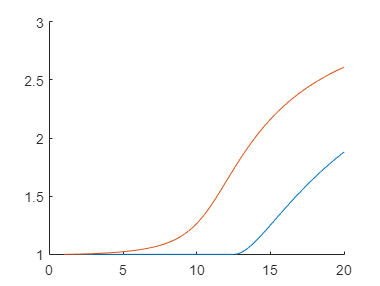


clear all
h = 2e-3;
z = h+eps ;
er = 10 ;
freq = 20.*1e9 ;
freqn = linspace(1e9,20e9,1001);
lambdan=3e8./freqn ;
lambda = 3e8./freq ;
k0 = 2*pi./lambda ;
ky = 0 ;
zeta0 = 120*pi ;
no_ofpt = 1001 ;

lst= k0.*sqrt(er) ;
krho = linspace(eps,lst,no_ofpt) ;
krho_norm = linspace(1,sqrt(er),no_ofpt) ;

% figure
% plot(krho./k0,abs(D))
% figure
% plot(krho./k0,abs(Dn))
% plot(freqn,abs(krholoop))
for ii = length(freqn):-1:1
    k0 = 2.*pi.* freqn(ii)./3e8 ;
    krho = krho_norm .* k0 ;
    [krhonte(ii),krho_newte(ii)] = IterativeMethod(h,er,freqn(ii),'GroundSlab','TE',krho) ;
    [krhontm(ii),krho_newtm(ii)] = IterativeMethod(h,er,freqn(ii),'GroundSlab','TM',krho) ;
end
figure
hold on
plot(freqn./1e9,abs(krhonte))
plot(freqn./1e9,abs(krhontm))
ylim([1 3]);

## Question 2: 

Write a Matlab routine to calculate the field contribution, in cylindrical coordinates,  associated to the TM0 surface wave excited by a half-wavelength dipole (l=15 mm, w=0.5 mm) on top of a grounded slab. Provide the following plots (h=2 mm, εr=10, f=10 GHz):

• Real and imaginary part variation of the electric field as a function of the radial  distance. 

• Amplitude variation of the electric field components as a function of z. 

• Amplitude variation of the electric field as a function of φ

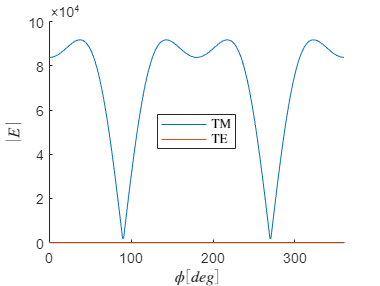

clear 
l = 15e-3 ;
w = 0.5e-3 ;
h = 2e-3 ;
er = 10; 
f= 10e9 ;
k0 = 2.*pi.* f./3e8 ;
no_ofpt = 1001 ;
phi = linspace(eps,2*pi,303) ;
lambdas = 3e8./(f.*sqrt(er)) ;
rho = 15 .*lambdas ;%linspace(eps,15 .*lambdas,202) ;% linspace(eps,1,200) ;
[RHO,PHI] = meshgrid(rho,phi) ;
z = linspace(eps,h+2e-3,202) ;

lst= k0.*sqrt(er) ;
krho = linspace(eps,lst,no_ofpt) ;

[~,kswTM] = IterativeMethod(h,er,f,'GroundSlab','TM',krho) ;
[VrTM,IrTM] = Residue_GroundSlab(k0,er,h,kswTM,z,f,'TM') ;
[Erho,Ephi,Ez] = SwFields(k0,kswTM,er,VrTM,IrTM,RHO,PHI,l,w) ;
EtotTM = sqrt( abs(Erho).^2 + abs(Ephi).^2 + abs(Ez).^2 ) ;

[~,kswTE] = IterativeMethod(h,er,f,'GroundSlab','TE',krho) ;
[VrTE,IrTE] = Residue_GroundSlab(k0,er,h,kswTE,z,f,'TE') ;
[Erho,Ephi,Ez] = SwFields(k0,kswTE,er,VrTE,IrTE,RHO,PHI,l,w) ;
EtotTE = sqrt( abs(Erho).^2 + abs(Ephi).^2 + abs(Ez).^2 ) ;

figure 
hold on
plot(rad2deg(phi),(EtotTM(:,length(rho))),'DisplayName','TM') ;
plot(rad2deg(phi),(EtotTE(:,length(rho))),'DisplayName','TE') ;
hold off
legend('Location','best','Interpreter','latex')
xlabel('$\phi[deg]$', 'Interpreter','latex');
ylabel('$\left|E\right|$', 'Interpreter','latex');
xlim([0 360])